# Wind Support to Bird migration

**Rapha****ë****l Nussbaumer1****,*********,** **Baptiste Schmid1** **,** **Silke Bauer1** **and Felix Liechti1** 

1 Swiss Ornithological Institute, Sempach, Switzerland 

* Correspondence: raphael.nussbaumer@vogelwarte.ch

Februray 12th, 2021

## Abstract

- Bird airspeed has a significant influence on energy depletion and consequently on survival of migrant bird. In a context of climatique change, understanding how bird navigate in the air is essential (use of windspeed, altitude, spring vs autumn)

- In this study, we examine the airspeed chosen by birds using 37 weather radar in Western Europe collected over a full year.

- Althgouh large variation of groundspeed were recorded, birds flew at a relative constant airspeed between season, altitude and region.

## Introduction

How do bird compensate for wind?

- strengh and direction of wind

- prefered direction

- altitude

- time/season

- timing of deparute: are bird compensating more early in the night?

- (- specie of bird, size)

## Data

Load basic data

load('coastlines.mat');% addpath('.function\')

### **Weather radar data**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ERAM, 2020) and processed as explained in Nussbaumer (2021) ([https://doi.org/10.1101/2021.03.08.434434](https://doi.org/10.1101/2021.03.08.434434)). The final dataset consists of bird density (ρ) [bird/km^3], bird flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo ([https://doi.org/10.5281/zenodo.3610184](https://doi.org/10.5281/zenodo.3610184))[.](https://zenodo.org/record/3610185.)

load('../2018/data/dc_corr.mat','dc'); 

NNT is Normalized night time (-1: sunset to 1 sunrise):

NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

Day grouping

[G_day,day_num]=findgroups(datenum(dateshift(dc(1).time,'start','day','nearest')));

We convert the structure data to matrix to ease of use later. At the same time, we do the following (1) convert orientation and speed into vector (NS, EW componenents as complex value), (2) remove data below ground level and most importantly (3) remove all interpolated data because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to the most only original data.

gs=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc)); dens=gs; sd_vvp=gs;
for i_d=1:numel(dc)
    % data to keep
    keep = true(size(dc(i_d).dens4));
    keep(repmat(1:dc(i_d).scatter_lim,numel(dc(1).time),1))=false; % remvove below ground
    keep(isnan(dc(i_d).dens3) | dc(i_d).dens3==0)=false; % remove when not interpolated
    keep(NNT(:,i_d)<-1 & NNT(:,i_d)>1,:) = false;
    
    % density
    tmp = dc(i_d).dens4; tmp(~keep)=nan;
    dens(:,:,i_d) = tmp;
    
    % variance of speed
    tmp = dc(i_d).sd_vvp; tmp(~keep)=nan;
    sd_vvp(:,:,i_d) = tmp;
        
    % groundspeed vector 
    keep(isnan(dc(i_d).u) | isnan(dc(i_d).v))=false; % remove when not interpolated
    tmp = dc(i_d).ub + 1i*dc(i_d).vb; tmp(~keep)=nan;
    gs(:,:,i_d) = tmp;
end

### **Climate Reanalaysis**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind and the air temperature t ([parmID=130](https://apps.ecmwf.int/codes/grib/param-db?id=130)) are downloaed from the ERA5 reanalysis ([https://doi.org/10.24381/cds.bd0915c6](https://doi.org/10.24381/cds.bd0915c6)) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). All three variables are linearly interpolated (time-space 4D) at each datapoint of the weather radar data (see [https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)](https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)) using the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

#### Air density

Aims is to build a function converting airspeed into energy, to do so, we need the air density on the same data format than the other variable (density, speed etc...)


$$\rho \;=\frac{p}{R_{\mathrm{specific}} T}$$


We  assume a constant specific gas constant

R_specific = 287.058; % J/(kg·K)

Pressure is taken from the altitude of each bin with the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

dc_pressure = (1-dc(1).alt*2.25577*10^(-5)).^(5.25588)*101325/100;

Air density is thus:

airdens=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc));
for i_d=1:numel(dc)
    airdens(:,:,i_d) = repmat(dc_pressure,numel(dc(i_d).time),1)*100 ./ dc(i_d).wt /R_specific; % hPa * Pa/hPa / K * kg*K/J = Pa*kg/J = kg/m^3
end

#### Windspeed

ws=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc));
for i_d=1:numel(dc)
    ws(:,:,i_d) = dc(i_d).ws; % windspeed vector 
end

#### **Airspeed**

Birds' groundspeed ($V_g$) and airspeed ($V_a$) can be computed respectively with


$$V_g =\sqrt{u^2 +v^2 }$$


and

 $V_a =\sqrt{{\left(u-U\right)}^2 +{\left(v-V\right)}^2 }$.

Airspeed vector 

as = gs-ws;

Speed norm

v_g = abs(gs);
v_a = abs(as);
v_w = abs(ws);

Speed orientation

% angle(gs)

**Plot radar data availability**

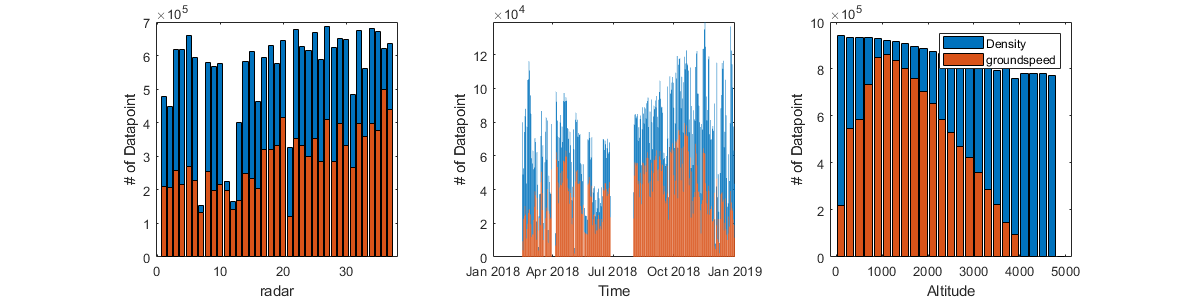

figure('position',[0 0 1200 300]);
subplot(1,3,1); hold on; box on;
bar(reshape(sum(sum(~isnan(dens) & dens~=0,1),2),1,[]))
bar(reshape(sum(sum(~isnan(v_g) & v_g~=0,1),2),1,[]))
xlabel('radar'); ylabel('# of Datapoint')
subplot(1,3,2);  hold on; box on;
bar(datetime(day_num,'convertfrom','datenum'), splitapply(@sum,sum(sum(~isnan(dens) & dens~=0,3),2),G_day'));
bar(datetime(day_num,'convertfrom','datenum'), splitapply(@sum,sum(sum(~isnan(v_g) & v_g~=0,3),2),G_day'));
axis tight;
xlabel('Time'); ylabel('# of Datapoint')
subplot(1,3,3);  hold on; box on;
bar(dc(1).alt,sum(sum(~isnan(dens) & dens~=0,1),3))
bar(dc(1).alt,sum(sum(~isnan(v_g) & dens~=0,1),3))
xlabel('Altitude'); ylabel('# of Datapoint')
legend('Density','groundspeed')

**Figure  : **Data availability measuring the total number of data point which are not NA or 0 for density and groundspeed (airspeed is same as groundspeed). 

- We have much fewer datapoint of speed than density. Most of them are at high altitude >4000m, where density is weak and speed is unrealiable. 

- Slightly more datapoint for German radar, but nothing important

- Annual coverage is relatively good, matching roughly the density (i.e., speed is only available when many bird are flying). 

## **Method**

We split the dataset in over space and time.

### **Split dataset : Seasonal**

 Over time, we define 4 periods: Early spring (March), Late spring (April), Early autumn (august-september) and late autumn (October). Note that we might want to redefine this period to match bird migration data (e.g., MTR). Here a coarse approach is to use entire month.

id_sp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-May-2018');
id_esp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-April-2018');
id_lsp = dc(1).time>datetime('1-April-2018') & dc(1).time<datetime('1-May-2018');
id_au = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Nov-2018');
id_eau = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Oct-2018');
id_lau = dc(1).time>datetime('1-Oct-2018') & dc(1).time<datetime('1-Nov-2018');

All periods combined

id_s = [id_esp; id_lsp; id_eau; id_lau];
id_s_name = {'March','April','Aug-sept.','October'};
id_s_col = [];
id_sp_col = [51 137 86]/255;
id_au_col = [229 103 7]/255;

We might also want to compare data of 2016 to see the difference.

id_2016 = dc(1).time>datetime('19-Sep-2018') & dc(1).time<datetime('9-Oct-2018');

### Split dataset: Geographic

We group radars in two groups of equal size based on their position along the general flow of migration (south-west / north east gradient with a flow orientation of `222°`). The Southern group include all French radar (18) exepect `frman` and the northern group include all germans (16), dutch (2) and Belgium (1) radars.

id_no = [true(16,1); false(12,1); true ;false(6,1) ;true(2,1)];
id_so = ~id_no;
id_de = [false; true(15,1); false(21,1)];
id_fr = [false(16,1); true(19,1); false(2,1)];
id_sno_col = [82 88 166; 178 164 34]/255;

Illustration

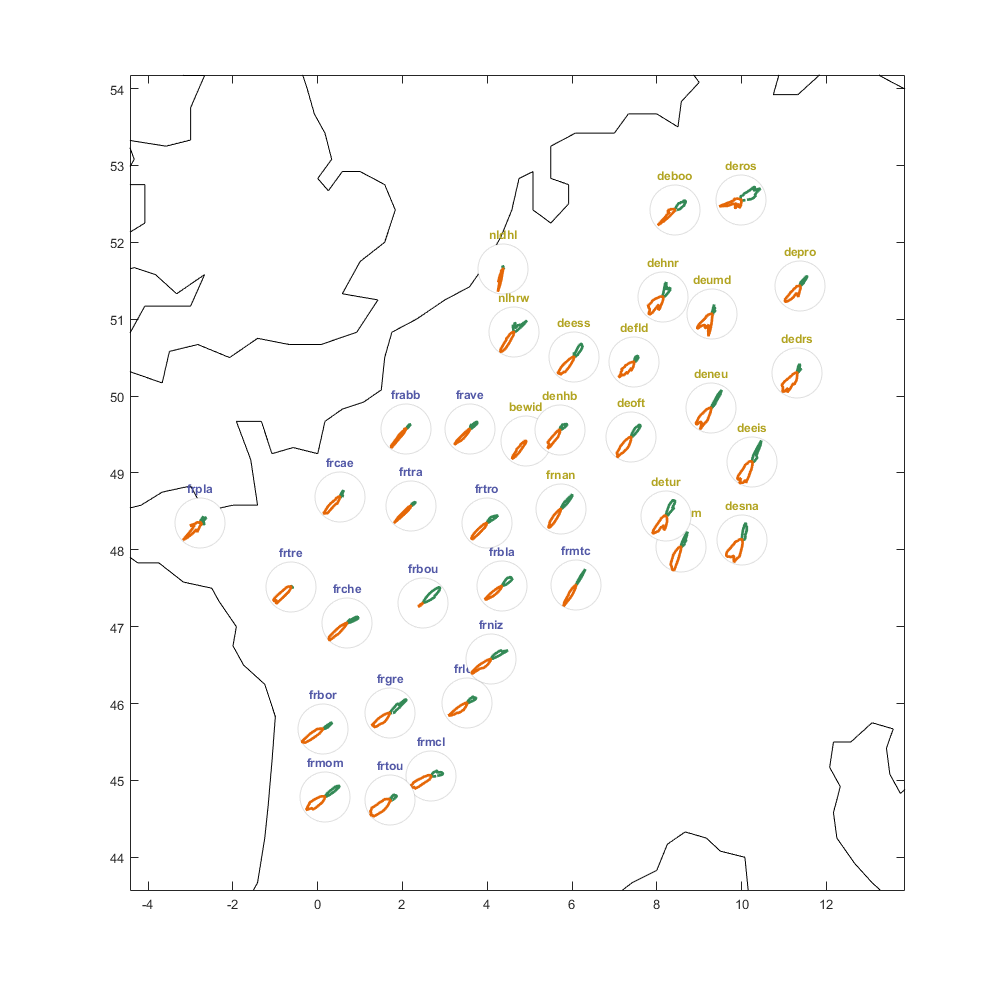

w=.07; h=0.05; m =.2; 
pw = @(lon) (lon-min([dc.lon]))/(max([dc.lon])-min([dc.lon]))*(1-2*m)+m;
ph = @(lat) (lat-min([dc.lat]))/(max([dc.lat])-min([dc.lat]))*(1-2*m)+m;

figure('position',[0 0 1000 1000]);
plot(coastlon,coastlat,'-k');
xlim([min([dc.lon]) max([dc.lon])])
ylim([min([dc.lat]) max([dc.lat])])

for i_d=1:numel(dc)
    [esp,hsp,~,~,Mdd(i_d,1)] = histvdens(dc(i_d).dd(id_sp,:), dens(id_sp,:,i_d).*v_g(id_sp,:,i_d), 100);
    [eau,hau,~,~,Mdd(i_d,2)] = histvdens(dc(i_d).dd(id_au,:), dens(id_au,:,i_d).*v_g(id_au,:,i_d), 100);
    %[e2016,h2016,~,~,Mdd(i_d,3)] = histvdens(dc(i_d).dd(id_2016,:), dens(id_2016,:,i_d).*v_g(id_2016,:,i_d), 100);
    
    subAX = axes('position',[pw(dc(i_d).lon)-w/2 ph(dc(i_d).lat)-h/2 w h]);
    %polarplot(deg2rad(e2016),h2016);hold on
    polarplot(deg2rad(esp),hsp,'Color',id_sp_col,'linewidth',2);hold on
    polarplot(deg2rad(eau),hau,'Color',id_au_col,'linewidth',2);
    %tmp=round(reshape(dens(id_sp,:,i_d).*v_g(id_sp,:,i_d),1,[])); tmp(isnan(tmp)) = 0;
    %polarhistogram(repelem(deg2rad(reshape(dc(i_d).dd(id_sp,:),1,[])), tmp),38); hold on;
    %polarplot(angle([Mdd(i_d,1) Mdd(i_d,1)]),[0 max(hsp)],'--','Color',id_sp_col,'LineWidth',2)
    %polarplot(angle([Mdd(i_d,2) Mdd(i_d,2)]),[0 max(hau)],'--','Color',id_au_col,'LineWidth',2)
    % polarplot(angle([Mdd(i_d,3) Mdd(i_d,3)]),[0 max([h2016;h2016])],'LineWidth',2)
    Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];
    title(dc(i_d).name,'Color',id_sno_col(id_no(i_d)+1,:))
end

**Figure : **Distribution of bird flight direction (groundspeed) weighted by the MTR (density x speed) for Spring (blue) and Autumn (red). Radars are grouped in the the northern (yellow) and southern (blue). *Location not correct yet...*

### Energy Calculation

In this section we define the energy power function, which provides the energy `eng` spent by a bird of mass `m`, wingspan `B` would spend flying at `vt` and with air density `airdens`. We also explore quickly the variation of optimal speed (i.e, lower energy) for different type of bird. 

Parameter for energy speding

k=1.2; % [-] Induced power factor (p. 45).
% m [kg] mass of bird.
gcst = 9.81; % [ms-2] gravity constant
% Vt [m/s] true speed (bird speed-wind speed)
% B [m] Wing span. 
% airdens = 1; % Air density 
Sb = @(m) 0.00813*m^0.666; % [m2] body frontal area
CDb = 0.1; % [-] body drag coefficient (p. 51).
Cpro = 8.4;
Ra = 7;

Define the function of energy

f_eng = @(Vt, airdens, m, B) (2*k*(m*gcst)^2)./(Vt*pi*B.^2.*airdens) + airdens.*Vt.^3*Sb(m)*CDb/2 + Cpro/Ra*1.05*k^(3/4)*m^(3/2)*gcst^(3/2)*Sb(m)^(1/4)*CDb^(1/4)./airdens.^(1/2)/B^(3/2);

Use data from appendix of Aurbach et al., (2020) for average mass and wingspan for migrant. 

Sp = table();
Sp.name = {'Willow Warbler'	'Tree Pipit'	'Common Chiffchaff'	'Spotted Flycatcher'	'Garden Warbler'	'Common Whitethroat'	'European Pied Flycatcher'	'Common Redstart'	'Wood Warbler'	'Eurasian Blackcap'}';
Sp.massmin = [8 	20	6	13	16	12	9	12	7	14]';
Sp.massmax = [10	25	9	19	23	18	15	20	12	20]';
Sp.wingmin = [17	25	15	23	20	19	22	21	20	22]';
Sp.wingmax = [22	27	21	25	24	23	24	24	24	24]';
Sp.abondance = [27.5	12.7	11.3	8.7	7.3	7.1	6.8	6.6	6.1	5.9]';

Compute average mass and wingspan

Sp.massmean = (Sp.massmin+Sp.massmax)/2/1000; % [m]
Sp.wingmean = (Sp.wingmin+Sp.wingmax)/2/100; % [kg]

Sort the table by mass

Sp=sortrows(Sp,'massmean')

Sp = 10×8 table
                name                massmin    massmax    wingmin    wingmax    abondance    massmean    wingmean
    ____________________________    _______    _______    _______    _______    _________    ________    ________

    {'Common Chiffchaff'       }       6          9         15         21         11.3        0.0075       0.18  
    {'Willow Warbler'          }       8         10         17         22         27.5         0.009      0.195  
    {'Wood Warbler'            }       7         12         20         24          6.1        0.0095       0.22  
    {'European Pied Flycatcher'}       9         15         22         24          6.8         0.012       0.23  
    {'Common Whitethroat'  

Compute the weighted average (accounting for abundance of each species

B_avg = sum(Sp.wingmean.*Sp.abondance/100);
m_avg = sum(Sp.massmean.*Sp.abondance/100);

**Energy as a function of species mass and wingspan**

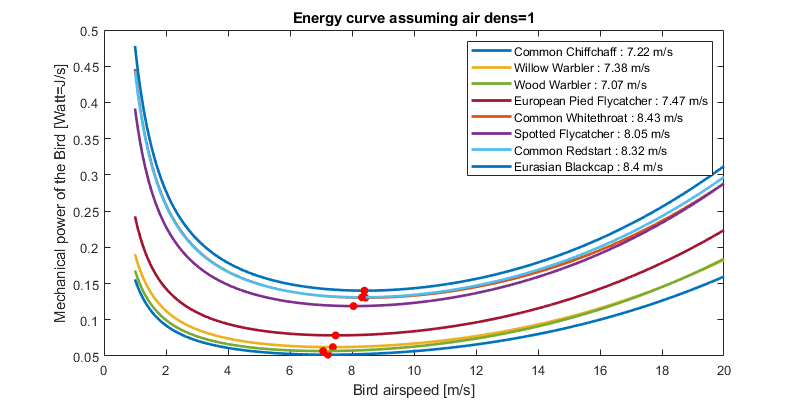

vt=1:0.01:20; 
p=nan(size(Sp,2),1);
figure('position',[0 0 800 400]); hold on; box on;
for i=1:size(Sp,2)
    Pvt = f_eng(vt, 1, Sp.massmean(i), Sp.wingmean(i));
    [~, tmp] = min(Pvt); 
    p(i)=plot(vt, Pvt,'LineWidth',2,'displayname',[Sp.name{i} ' : ' num2str(vt(tmp)) ,' m/s' ]);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title('Energy curve assuming air dens=1')

The variation of optimal speed does not seem huge with these bird (7.2 - 8.4 m/s). But, we are  missing some bigger bird (e.g., thrush).

**Energy as a function of air density**

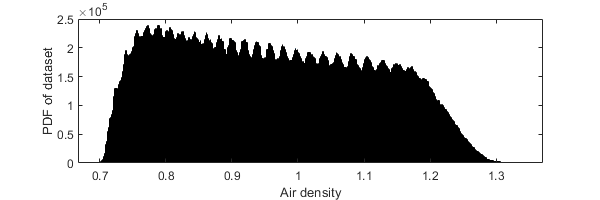

figure('position',[0 0 600 200]); histogram(airdens); xlabel('Air density'); ylabel('PDF of dataset')

Air density presents in the database.

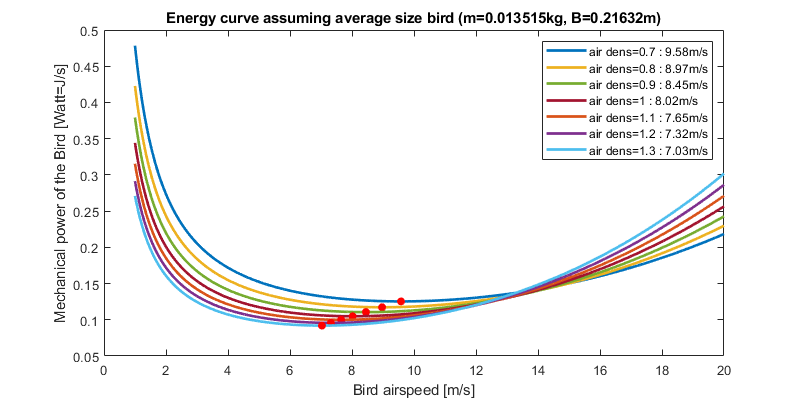

figure('position',[0 0 800 400]); hold on; box on;
ad = 0.7:0.1:1.3;
p=nan(size(ad));
for i = 1:numel(ad)
    Pvt = f_eng(vt,ad(i),m_avg,B_avg);
    [~, tmp] = min(Pvt); 
    p(i)=plot(vt, Pvt,'LineWidth',2,'displayname',['air dens=' num2str(ad(i)) ' : ' num2str(vt(tmp)) 'm/s']);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title(['Energy curve assuming average size bird (m=' num2str(m_avg) 'kg, B=' num2str(B_avg) 'm)'])

Note that air density plays also a role in the optimale speed of bird, whithin the variation of the airdensity observed (computed from ERA dataset). 

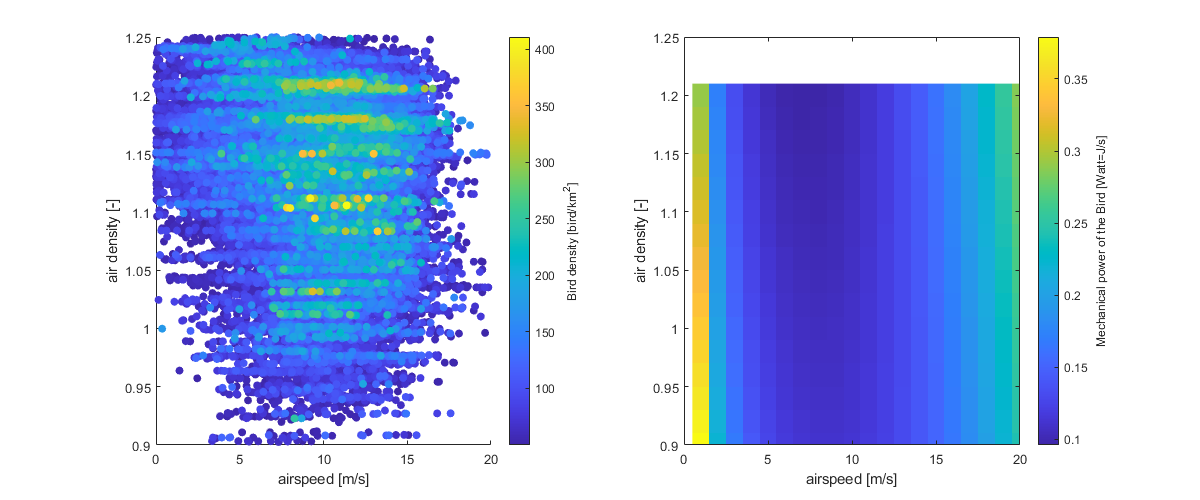

[V,A] = meshgrid(1:20,0.9:0.02:1.2);
E = f_eng(V, A, m_avg,B_avg);
lim = 50;
tmp = [v_a(dens>lim) airdens(dens>lim) dens(dens>lim)];
[~,idx] = sort(tmp(:,3)); % sort just the first column
tmp = tmp(idx,:);
figure('position',[0 0 1200 500]); 
subplot(1,2,1)
scatter(tmp(:,1),tmp(:,2),[],tmp(:,3),'filled')
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Bird density [bird/km^2]'; 
xlim([0 20]); ylim([0.9 1.25]);
subplot(1,2,2);
imagesc(V(1,:),A(:,1),E); 
ax = gca; ax.YDir = 'normal';
xlim([0 20]); ylim([0.9 1.25]);
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Mechanical power of the Bird [Watt=J/s]'; 

In this figure, I compare the airspeed/airdensity usage of bird with the optimal according to mechanical theory. Left subplot shows the actually usage (warmer color=more bird), and right panel shows the optimal for an average sized bird (colder cooler=more optimal). 

- Air density does not playa big role

- Bird should really not fly lower than 3m/s, yet we do observed some airspeed very low. 

- Generally, highest density are present with airspeed slightly higher than theory (9-12m/s vs 7-10 m/s).

Compute the energy for the entire dataset assuming an averaged size bird.

eng = f_eng(v_a, airdens, m_avg, B_avg);

### Reshape data as table

Reshape into table to reduce space and help in the analysis

% [tmp_time, tmp_alt, tmp_radar] = meshgrid(dc(1).time,dc(1).alt,1:37);
% T = table(dens(:),v_a(:),v_w(:),angle(ws(:)),tmp_time(:),tmp_alt(:),tmp_radar(:),'VariableNames',{'dens','airspeed','windspeed','windorien','time','alt','radar'});
% T

## Anaylsis and Results

### Air vs Ground Overall

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[b,h,Mg,Sg] = histvdens(v_g, dens);
bar(b,h,'FaceAlpha',0.6);
[b,h,Ma,Sa] = histvdens(v_a, dens);
bar(b,h,'FaceAlpha',0.6);
%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel('Bird speed [m/s]'); box on
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(1,2,2); hold on;
[~, id] = sort(dens(:)); id2 = id(dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(v_a(id2),v_g(id2),[],dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2); box on
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; c.Label.String='Bird density [bird/km^2]';

Histograms of airspeed and ground speed are normalized by the density of bird, that is, each bin of bird speed is multiply not by the number of occuruance in the dataset but by the sum of all bird density flying at this speed. 

(a) Bird move (i.e. groundspeed) at around 10.5 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.4m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

### Air vs Ground **during the season**

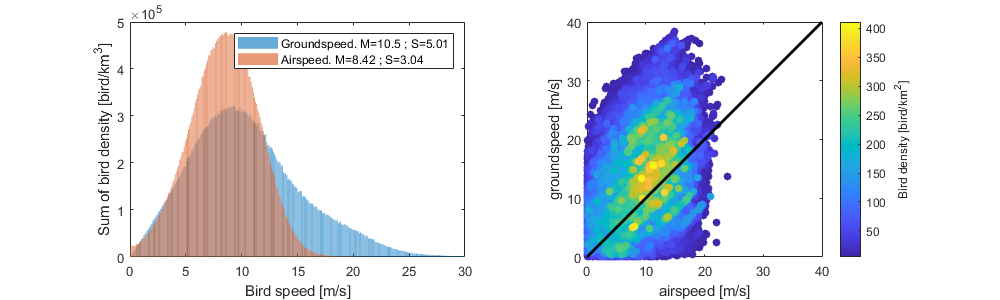

figure('position',[0 0 1200 1000]);

subplot(2,3,[1 2]); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_sp,:,:),dens(id_sp,:,:));
bar(b,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_sp,:,:),dens(id_sp,:,:));
bar(b,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Spring. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]); box on

subplot(2,3,[4 5]); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_au,:,:),dens(id_au,:,:));
bar(b,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_au,:,:),dens(id_au,:,:));
bar(b,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Autumn. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]); box on


for i_s=1:size(id_s,1)
    subplot(4,3,(i_s-1)*3+3); hold on
    [b,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
    bar(b,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    [b,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
    bar(b,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
    legend; xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,:))))/1000000,3) ' M']);xlim([0 30]);
    box on;
end

While the bird are moving with quite different ground speed (blue) regime in Spring (left) and Autumn (right), their actual airspeed (red) is impresively similar. Note that the total number of bird measured is very different in spring (8M bird/km3) and autumn (17M bird/km3). This is because spring is shorter, thus less measurement and it doesn't represent the actual number of bird flying through. 

figure('position',[0 0 600 800]);
subplot(5,1,1); hold on
[b,h,Mg,Sg] = histvdens(eng, dens, 0.09:0.001:0.15);
bar(b,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);xlim([0.09 0.13])
legend; xlabel(['Mechanical power of the Bird [Watt=J/s].Total nb: ' num2str(nansum(nansum(nansum(dens)))/1000000,3) ' M']); 
box on; ylabel('PDF - All year')
for i_s=1:size(id_s,1)
    subplot(5,1,i_s+1); hold on
    [b,h,Mg,Sg] = histvdens(eng(id_s(i_s,:),:,:), dens(id_s(i_s,:),:,:),0.09:0.001:0.15);
    bar(b,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);xlim([0.09 0.13])
    legend; xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,:))))/1000000,3) ' M']); 
    box on; ylabel(['PDF - ' id_s_name{i_s}])
end

Distribution of the energy spend by bird for various period of the year. We account for the density of bird (i.e., how many bird are spending this energy). But we do not account for change of mass. 

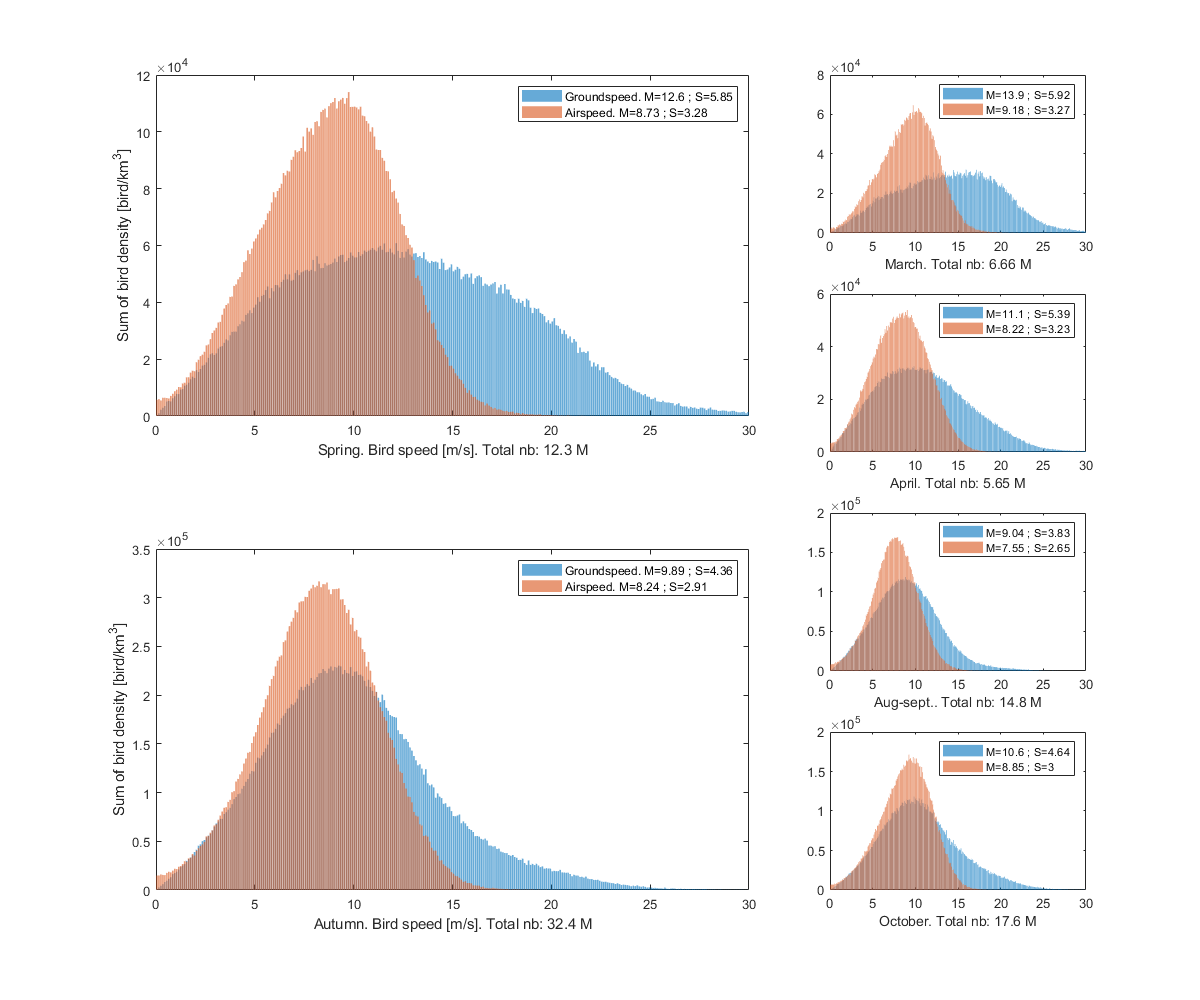

figure('position',[0 0 400 1000]);

subplot(3,1,1); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_sp,:,:),dens(id_sp,:,:),0:1:30);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.1 .1 .1],'EdgeAlpha',0);
[b,h,Mg,Sg] = histvdens(v_g(id_au,:,:),dens(id_au,:,:),0:1:30);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Groundspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(3,1,2); hold on;
[b,h,Ma,Sa] = histvdens(sd_vvp(id_sp,:,:),dens(id_sp,:,:),1.5:0.2:6);

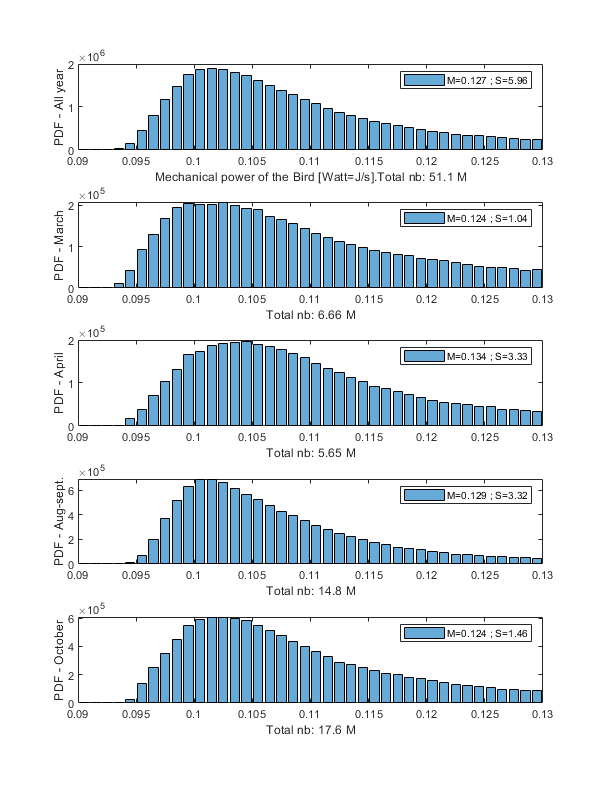

bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.1 .1 .1],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(sd_vvp(id_au,:,:),dens(id_au,:,:),1.5:0.2:6);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Spectrum width [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([1.5 6]);

subplot(3,1,3); hold on;
[b,h,Ma,Sa] = histvdens(v_a(id_sp,:,:),dens(id_sp,:,:),5:1:20);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.1 .1 .1],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(v_a(id_au,:,:),dens(id_au,:,:),5:1:20);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Airspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([5 20]);

This figure reproduces Figure .. of Horton et al. 2016 ([https://doi.org/10.1642/AUK-16-105.1](https://doi.org/10.1642/AUK-16-105.1)).

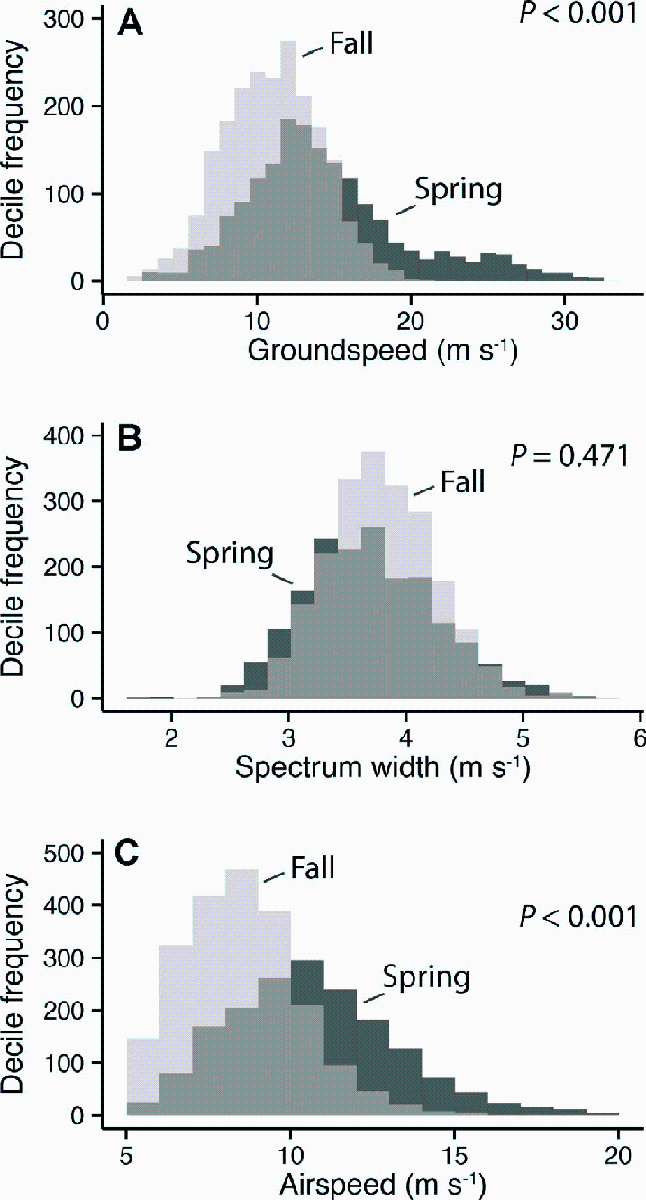

### Air vs Ground in space

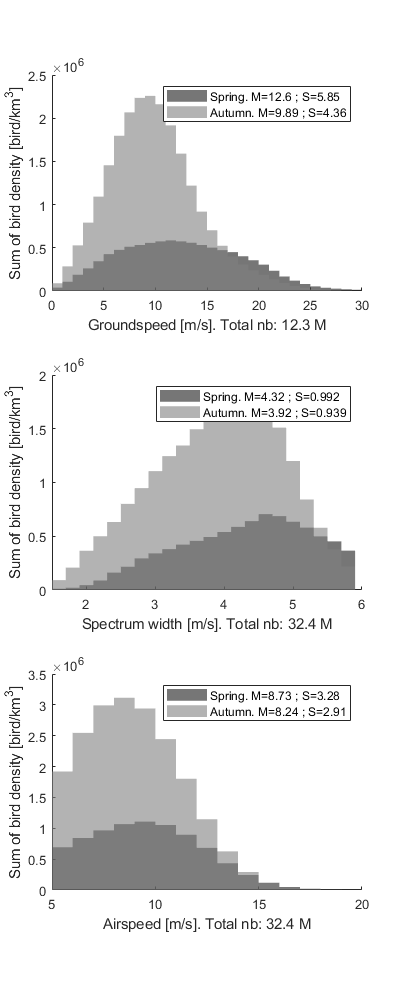

figure('position',[0 0 1200 600]);

subplot(2,2,1); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_so),dens(id_sp,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_so),dens(id_sp,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_so),dens(id_sp,:,id_so));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[b,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_so),dens(id_sp,:,id_so));
yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend; xlabel(['South-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_so),3)))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(2,2,2); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_au,:,id_so),dens(id_au,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_au,:,id_so),dens(id_au,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mw,Sw] = histvdens(v_w(id_au,:,id_so),dens(id_au,:,id_so));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[b,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_so),dens(id_au,:,id_so));
yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])

legend; xlabel(['South-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_so),3)))/1000000,3) ' M']);

subplot(2,2,3); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_no),dens(id_sp,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_no),dens(id_sp,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_no),dens(id_sp,:,id_no));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[b,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_no),dens(id_sp,:,id_no));
yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['North-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_no),3)))/1000000,3) ' M']);

subplot(2,2,4); hold on;
[b,h,Mg,Sg] = histvdens(v_g(id_au,:,id_no),dens(id_au,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Ma,Sa] = histvdens(v_a(id_au,:,id_no),dens(id_au,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mw,Sw] = histvdens(v_w(id_au,:,id_no),dens(id_au,:,id_no));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[b,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_no),dens(id_au,:,id_no));
yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; xlim([0 30])
legend; xlabel(['North-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_no),3)))/1000000,3) ' M']);  

In this figure, we seperate both in term of region: France (top) and Germany (bottom) and Season: Spring (left) and Autumn (right). We also added the windspeed in yellow to help explain the difference between France and Germany.

Groundspeed is suprinsigly much higher in the radar in France, particularly in Spring (15.7 m/s vs 10.8 for Germany). However, airspeed is much more similar between France and Germany (9.6m/s vs 8.3 m/s for Germany). This difference in groundspeed uniquely is well explained by the windspeed (yellow). Indeed, in France birds benefit from a better wind speed (8.7m/s vs 7.1m/s germany) allowing them to increase their groundspeed. 

Note that this windspeed is the norm of the vector and not a projection on the prefered direction of migration. However, it is normalized by the number of bird in the air, thus the windspeed is representative of the wind support of bird migration. 

Is this a pattern unique to 2018? See AverageWind.html

More figures are plotted in Supplementary material down the page. 

figure('position',[0 0 1600 600]);

for i_s=1:size(id_s,1)
    subplot(2,4,i_s); hold on;
    [b,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    bar(b,h,'FaceAlpha',0.6);
    if i_s==1, ylabel('France'), end
    [b,h,Mw,Sw] = histvdens(v_w(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(b,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]); box on;

    subplot(2,4,i_s+4); hold on;
    [b,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(v_w(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    if i_s==1, ylabel('Germany'), end
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(b,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_de),3)))/1000000,3) ' M']);xlim([0 30]); box on;
end

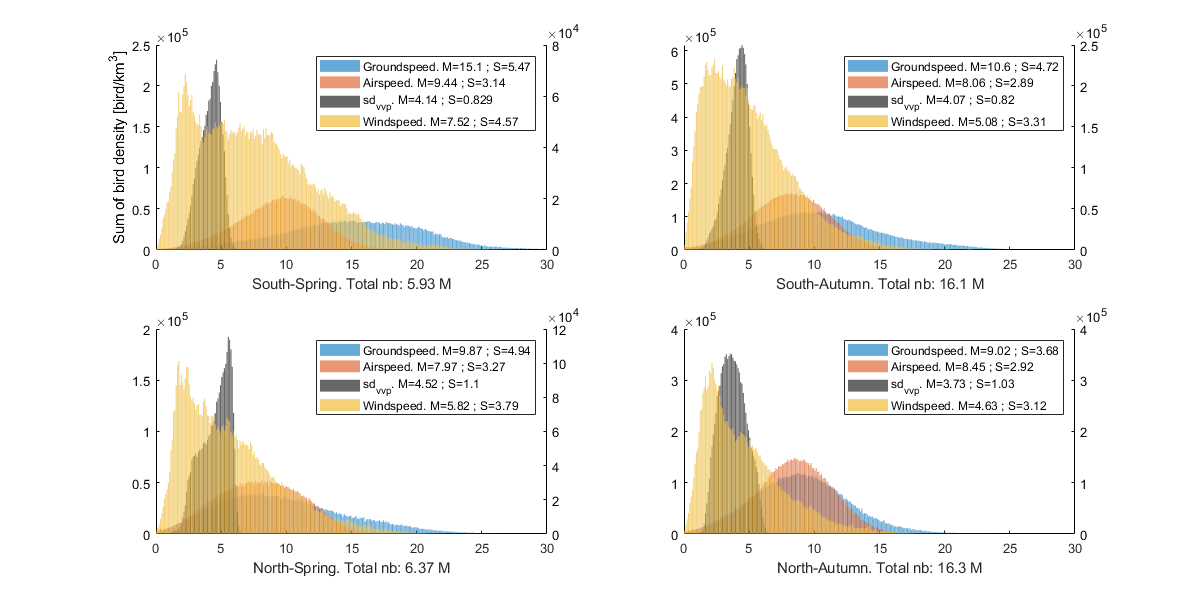

Mg=nan(numel(dc),size(id_s,1)); Mgw=Mg; gu=Mg; gv=Mg; gwu=Mg; gwv=Mg; awu=Mg; awv=Mg; wwu=Mg; wwv=Mg; Maw=Mg; Mww=Mg;
for i_d = 1:numel(dc)
    for i_s = 1:size(id_s,1)
        Md(i_d,i_s) = nanmean(reshape(dens(id_s(i_s,:),:,i_d),1,[]));
        
        Mg(i_d,i_s) = nanmean(reshape(      v_g(id_s(i_s,:),:,i_d) ,1,[]));

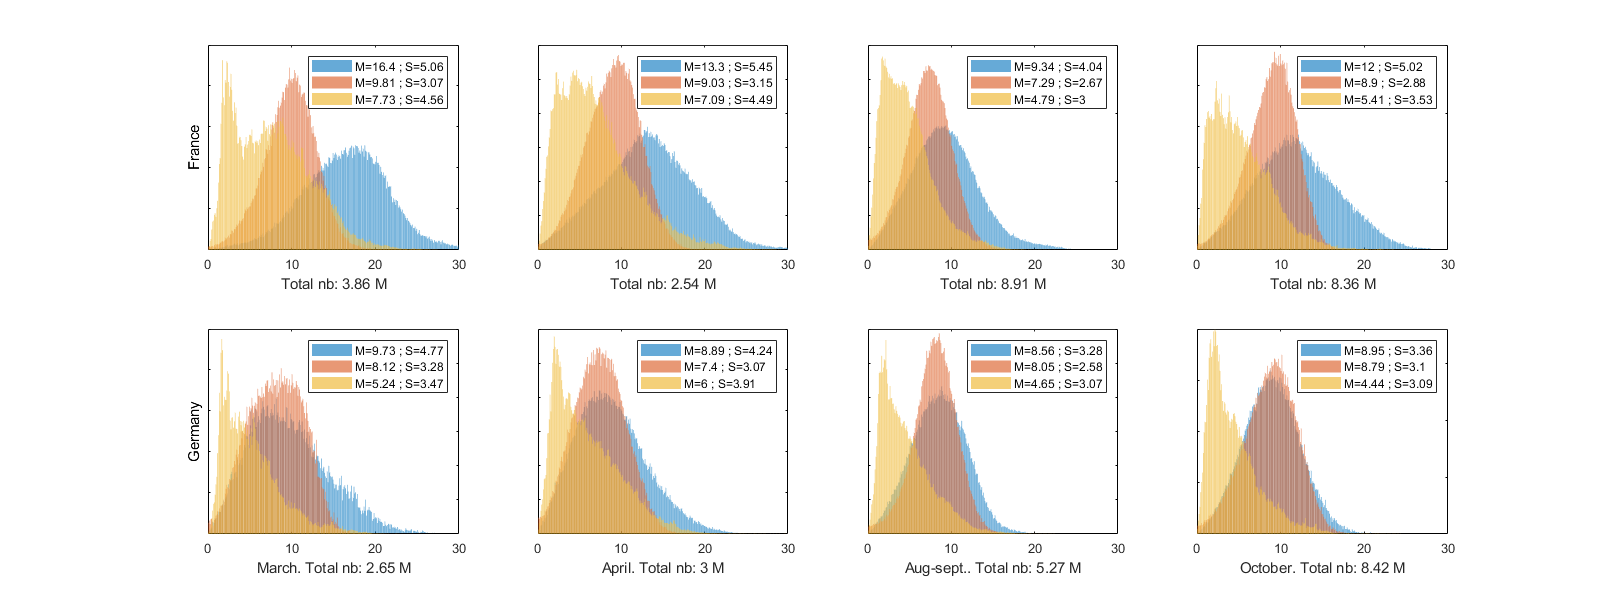

        gu(i_d,i_s) = nanmean(reshape( real( gs(id_s(i_s,:),:,i_d)),1,[]));
        gv(i_d,i_s) = nanmean(reshape( imag( gs(id_s(i_s,:),:,i_d)),1,[]));
        
        Mw(i_d,i_s) = nanmean(reshape(      v_w(id_s(i_s,:),:,i_d) ,1,[]));
        wu(i_d,i_s) = nanmean(reshape( real( ws(id_s(i_s,:),:,i_d)),1,[]));
        wv(i_d,i_s) = nanmean(reshape( imag( ws(id_s(i_s,:),:,i_d)),1,[]));
        
        [~,~,Mgw(i_d,i_s)] = histvdens(      v_g(id_s(i_s,:),:,i_d) ,dens(id_s(i_s,:),:,i_d));
        [~,~,gwu(i_d,i_s)] = histvdens( real( gs(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,gwv(i_d,i_s)] = histvdens( imag( gs(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        
        [~,~,Maw(i_d,i_s)] = histvdens(      v_a(id_s(i_s,:),:,i_d) ,dens(id_s(i_s,:),:,i_d));
        [~,~,awu(i_d,i_s)] = histvdens( real( as(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,awv(i_d,i_s)] = histvdens( imag( as(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        
        [~,~,Mww(i_d,i_s)] = histvdens(      v_w(id_s(i_s,:),:,i_d) ,dens(id_s(i_s,:),:,i_d));
        [~,~,wwu(i_d,i_s)] = histvdens( real( ws(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,wwv(i_d,i_s)] = histvdens( imag( ws(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
    end
end

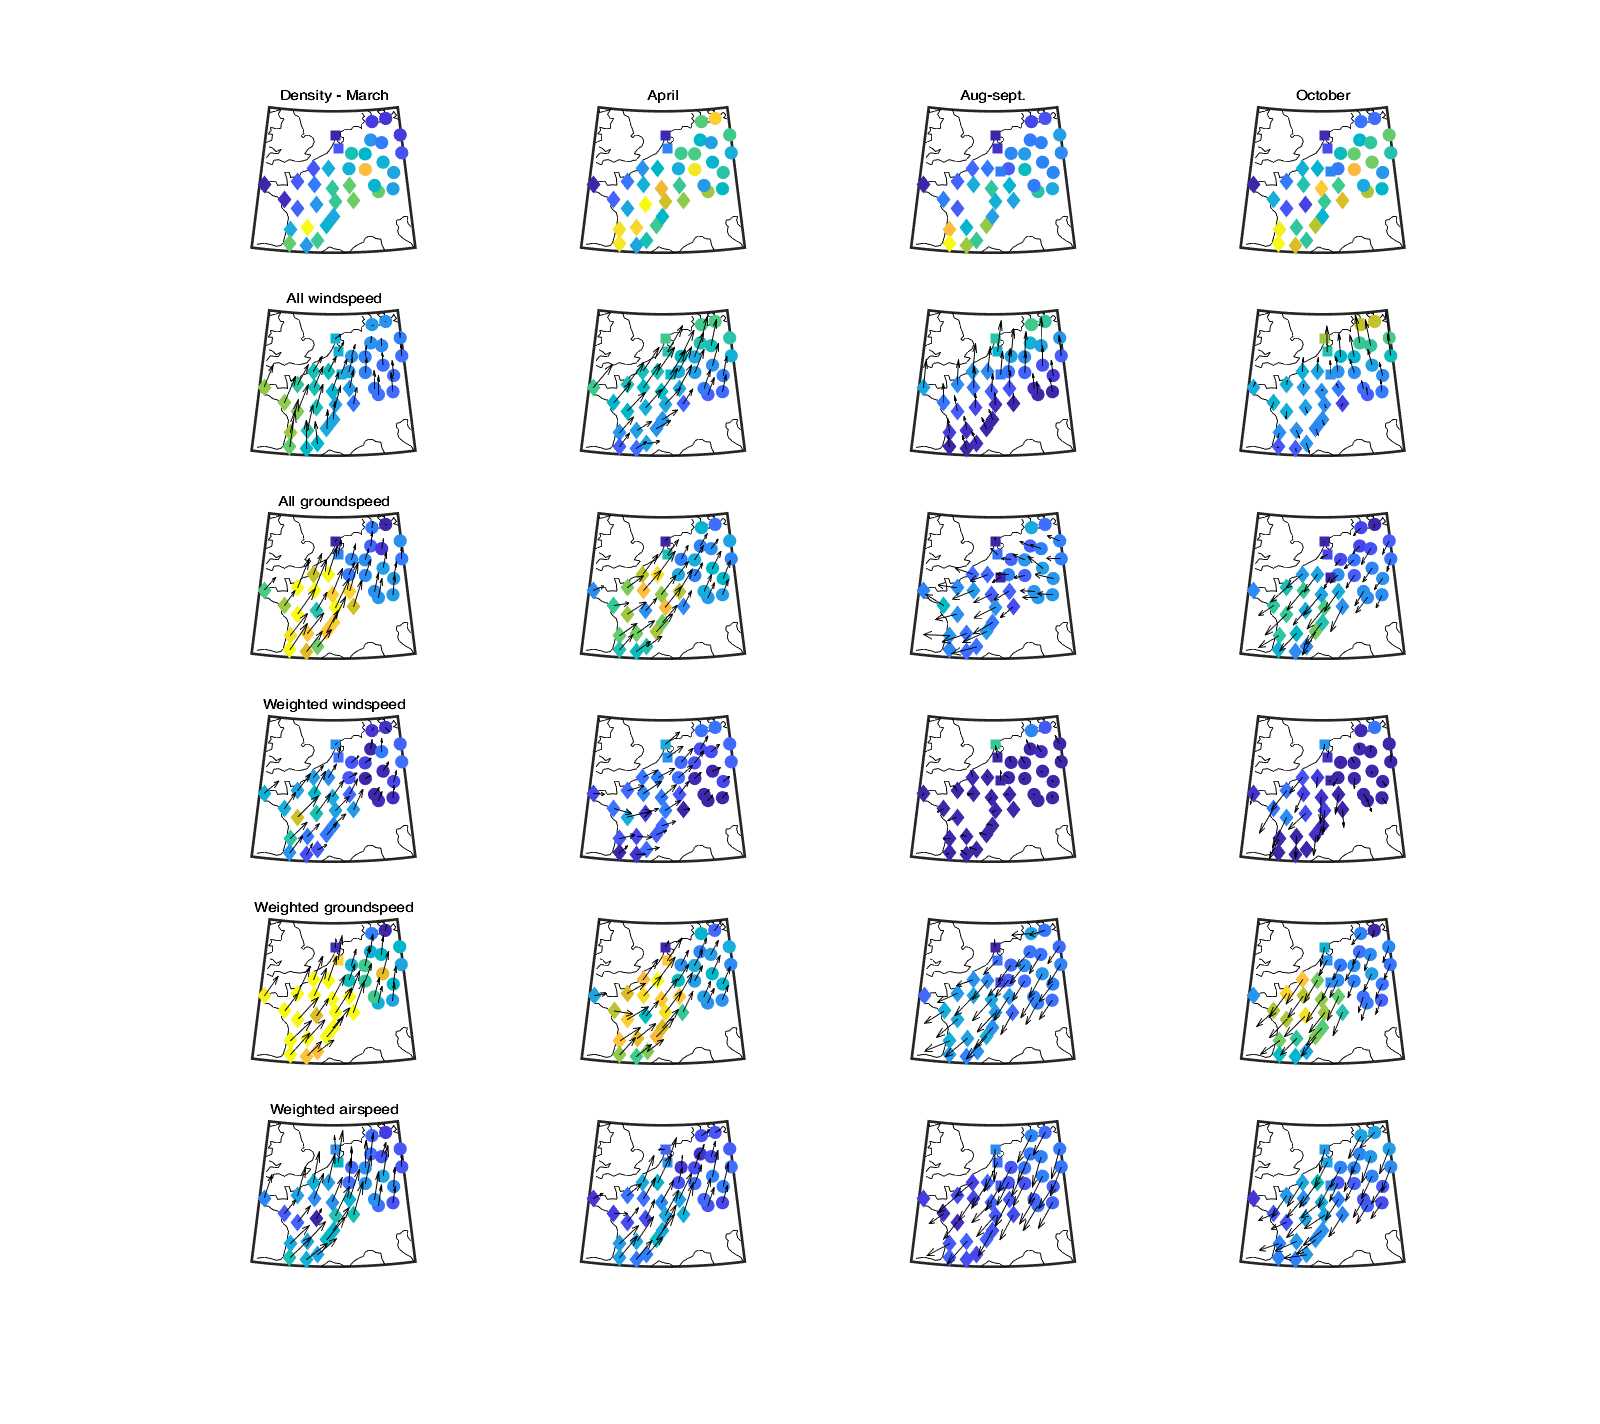

figure('position',[0 0 1600 2400]); 
for i_s = 1:size(id_s,1)
    subplot(6,4,i_s); hold on; 
    title(id_s_name{i_s})
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Md(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Md(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Md(id_fr,i_s),'d','filled');  
    if i_s==1, title(['Density - ' id_s_name{i_s}]); end

    subplot(6,4,i_s+4); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mw(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wu(:,i_s),wv(:,i_s),'k')
    caxis([6 16]) 
    if i_s==1, title('All windspeed'); end
    
    subplot(6,4,i_s+8); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mg(id_de,i_s),'filled'); 
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mg(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mg(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',gu(:,i_s),gv(:,i_s),'k')
    caxis([6 16]) 
    if i_s==1, title('All groundspeed'); end
    
    subplot(6,4,i_s+12); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mww(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mww(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mww(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wwu(:,i_s),wwv(:,i_s),'k')
    caxis([6 16])
    if i_s==1, title('Weighted windspeed'); end
    
    subplot(6,4,i_s+16); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mgw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mgw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mgw(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',gwu(:,i_s),gwv(:,i_s),'k')
    caxis([6 16]) 
    if i_s==1, title('Weighted groundspeed'); end
    
    subplot(6,4,i_s+20); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Maw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Maw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Maw(id_fr,i_s),'d','filled');
    quiverm([dc.lat]',[dc.lon]',awu(:,i_s),awv(:,i_s),'k')
    caxis([6 16])
    if i_s==1, title('Weighted airspeed'); end
    
end

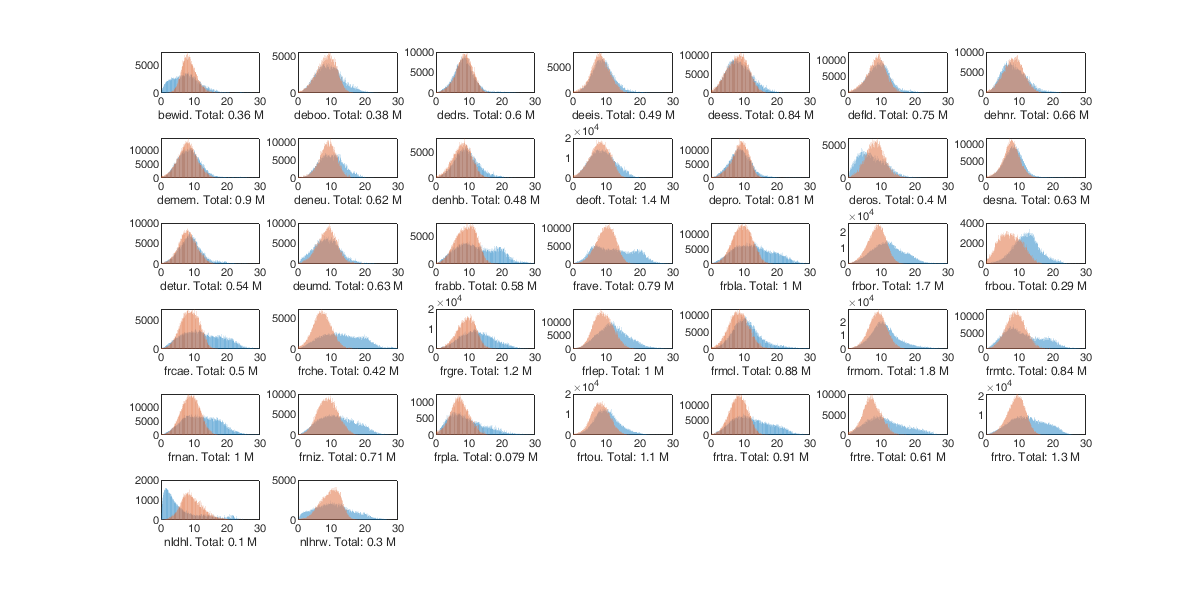

figure('position',[0 0 1200 600]);
Mg=nan(1,numel(dc));Sg=Mg;Ma=Mg;Sa=Mg;Mw=Mg;Sw=Mg;
for i_d= 1:numel(dc)
    subplot(6,7,i_d); hold on
    [b,h,Mg(i_d), Sg(i_d)] = histvdens(v_g(:,:,i_d),dens(:,:,i_d));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma(i_d), Sa(i_d)] = histvdens(v_a(:,:,i_d),dens(:,:,i_d));
    bar(b,h,'FaceAlpha',0.6);
    histogram(v_g(:,:,i_d),'Normalization', 'pdf','FaceAlpha',0.6,'EdgeAlpha',0)
    %[e,h,Mw(i_d), Sw(i_d)] = histvdens(v_w(:,:,i_d),dens(:,:,i_d));
    %bar(e,h,'FaceAlpha',0.6);
    % legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ dc(i_d).name '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]); box on;
end

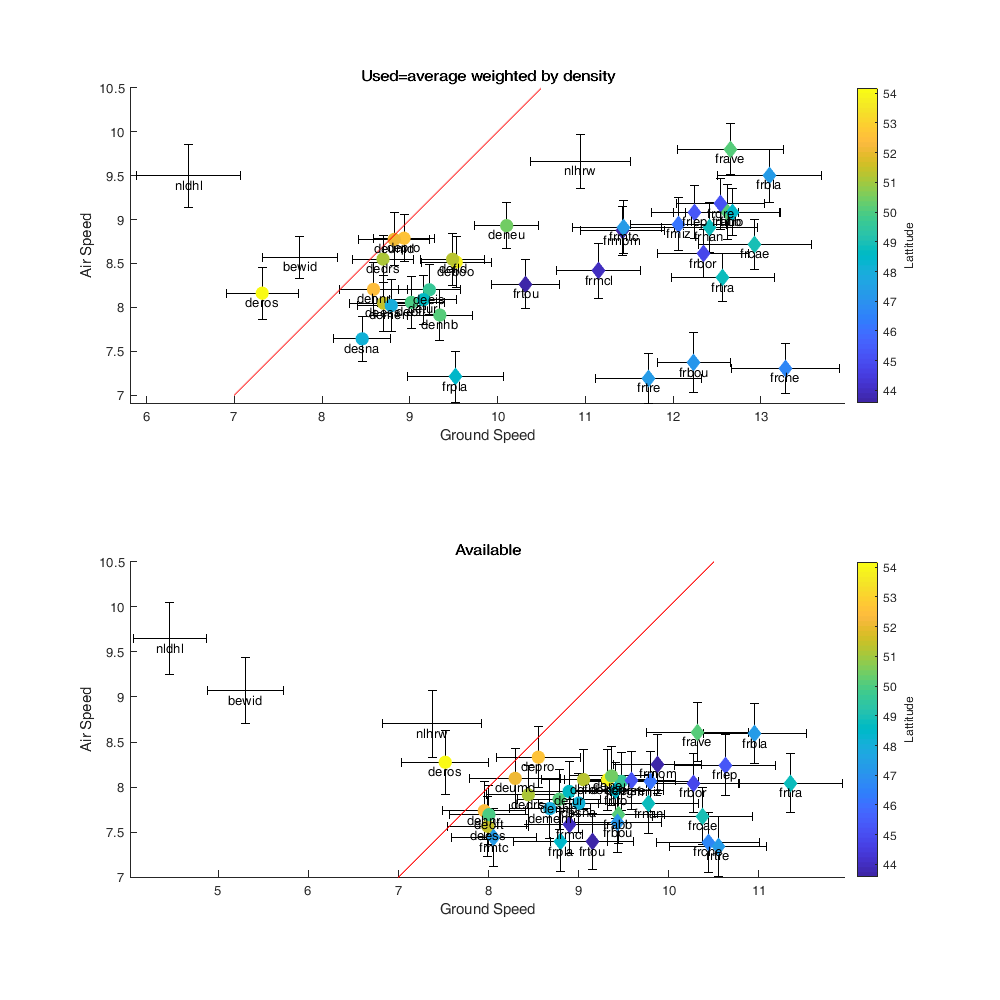

figure('position',[0 0 1000 1000]); 
subplot(2,1,1);hold on;
eb(1) = errorbar(Mg,Ma,Sg/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg,Ma,Sa/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg(id_de),Ma(id_de),100,[dc(id_de).lat],'filled');
scatter(Mg(~id_de&~id_fr),Ma(~id_de&~id_fr),100,[dc(~id_de&~id_fr).lat],'s','filled');
scatter(Mg(id_fr),Ma(id_fr),100,[dc(id_fr).lat],'d','filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg,Ma-0.1,{dc.name},'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude';
title('Used=average weighted by density')
subplot(2,1,2); hold on;
Mg2=nanmean(reshape(v_g,[],numel(dc)));
Ma2=nanmean(reshape(v_a,[],numel(dc)));
Sg2=nanstd(reshape(v_g,[],numel(dc)));
Sa2=nanstd(reshape(v_a,[],numel(dc)));
eb(1) = errorbar(Mg2,Ma2,Sg2/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg2,Ma2,Sa2/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg2(id_de),Ma2(id_de),100,[dc(id_de).lat],'filled');
scatter(Mg2(~id_de&~id_fr),Ma2(~id_de&~id_fr),100,[dc(~id_de&~id_fr).lat],'s','filled');
scatter(Mg2(id_fr),Ma2(id_fr),100,[dc(id_fr).lat],'d','filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg2,Ma2-0.1,{dc.name},'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude'; title('Available')

There is a very strong difference visible at the country level. In Germany, the difference between airspeed and ground speed is very small while in French, the pattern observed earlier is most consistant.

### Air vs Ground in a**ltitude**

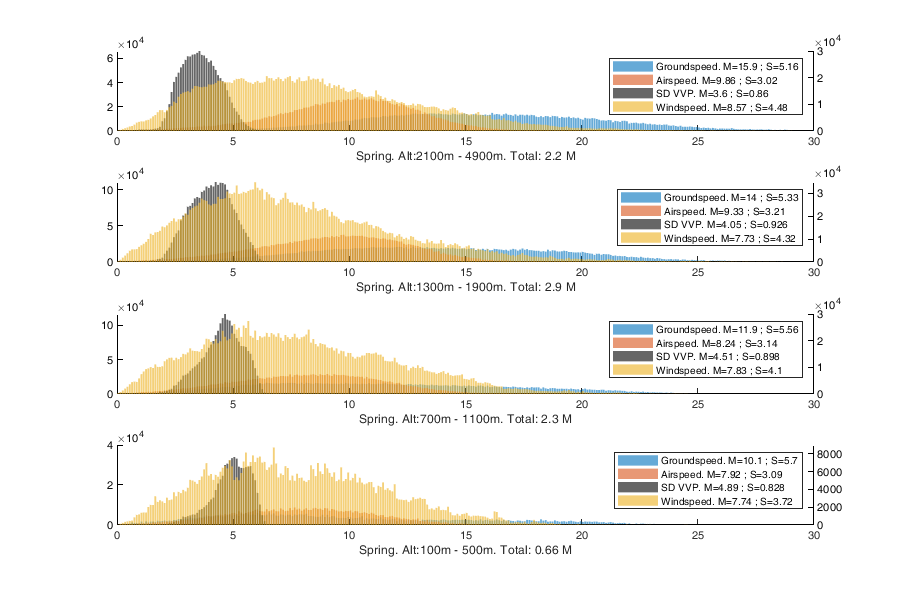

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [b,h,Mg,Sg] = histvdens(v_g(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(v_a(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(v_w(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis right; bar(b,h,'FaceAlpha',0.6);
    [b,h, Ms, Ss ] = histvdens(sd_vvp(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis left; bar(b,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Spring. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_sp,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

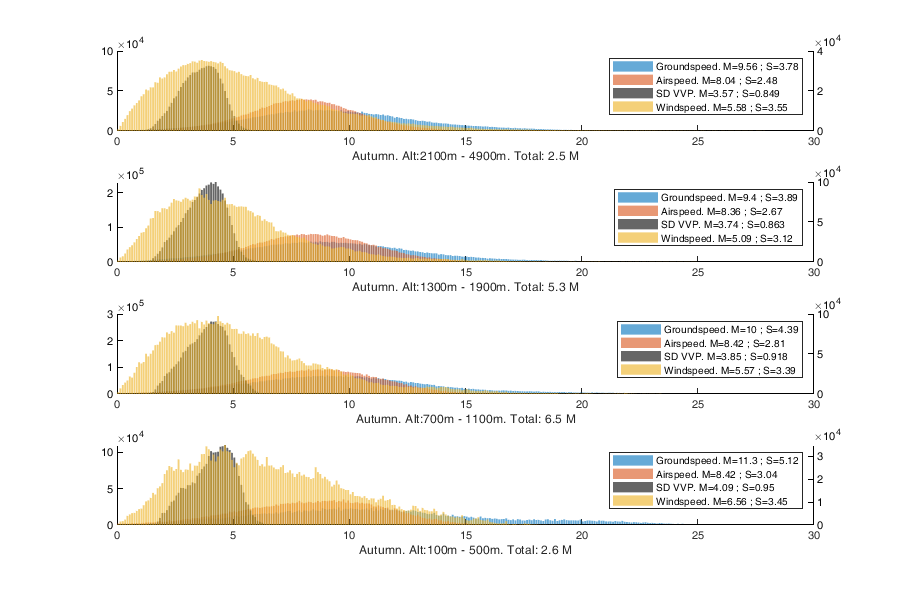

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
 for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [b,h,Mg,Sg] = histvdens(v_g(id_au,id_a,:),dens(id_au,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(v_a(id_au,id_a,:),dens(id_au,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(v_w(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis right; bar(b,h,'FaceAlpha',0.6);
    [b,h, Ms, Ss] = histvdens(sd_vvp(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis left; bar(b,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Autumn. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_au,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

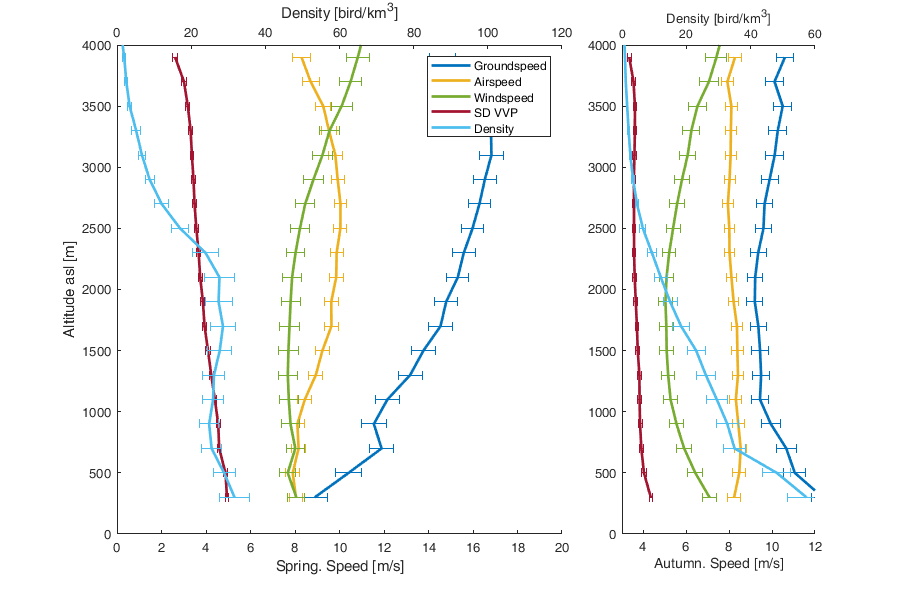

Mg = nan(numel(dc(1).alt),2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_au,i_a,:),dens(id_au,i_a,:));
end

figure('position',[0 0 900 600]);
subplot(1,3,[1 2]); hold on;
tmp = errorbar(Mg(:,1),dc(1).alt,Sg(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,1),dc(1).alt,Sa(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,1),dc(1).alt,Sw(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,1),dc(1).alt,Ss(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
xlim([0 20]);ylabel('Altitude asl [m]'); xlabel('Spring. Speed [m/s]'); ylim([0 4000]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,1),dc(1).alt,Sd(:,1)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 120]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(1,3,3); hold on;
tmp = errorbar(Mg(:,2),dc(1).alt,Sg(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,2),dc(1).alt,Sa(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,2),dc(1).alt,Sw(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,2),dc(1).alt,Ss(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([3 12]); xlabel('Autumn. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,2),dc(1).alt,Sd(:,2)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 60])

Thick line represent the mean and the error bird the 1 standard deviation computed at each altitude bin and weighted by the density of bird. `sd_vvp` is the variance of groundspeed within the bin. The size of the Spring and Autumn subplot are scaled to have the same axis scale. 

Ground speed generally increase with altitude, but airspeed increase much less as windspeed explain in great part the increase of groundspeed. This effect is visible in both spring and autumn. The profile of groundspeed and windspeed matches well in both season, making the airspeed profile relatively straight (at least in comparison to windspeed and groundspeed). 

The decrease of `sd_vvp` with altitude indicates a more directional flow of bird in high altitude (less variance in groundspeed). This variability is certainly explained by bird flying in more diverse direction at low elevation and consequently reducing the average ground speed (and airspeed!) of the bin as measure by weather radar. One could try to argue that the "angle" (derivative with regard to altitude) in sd_vvp and airspeed are matching (e.g. 100-500m bin in autumn).

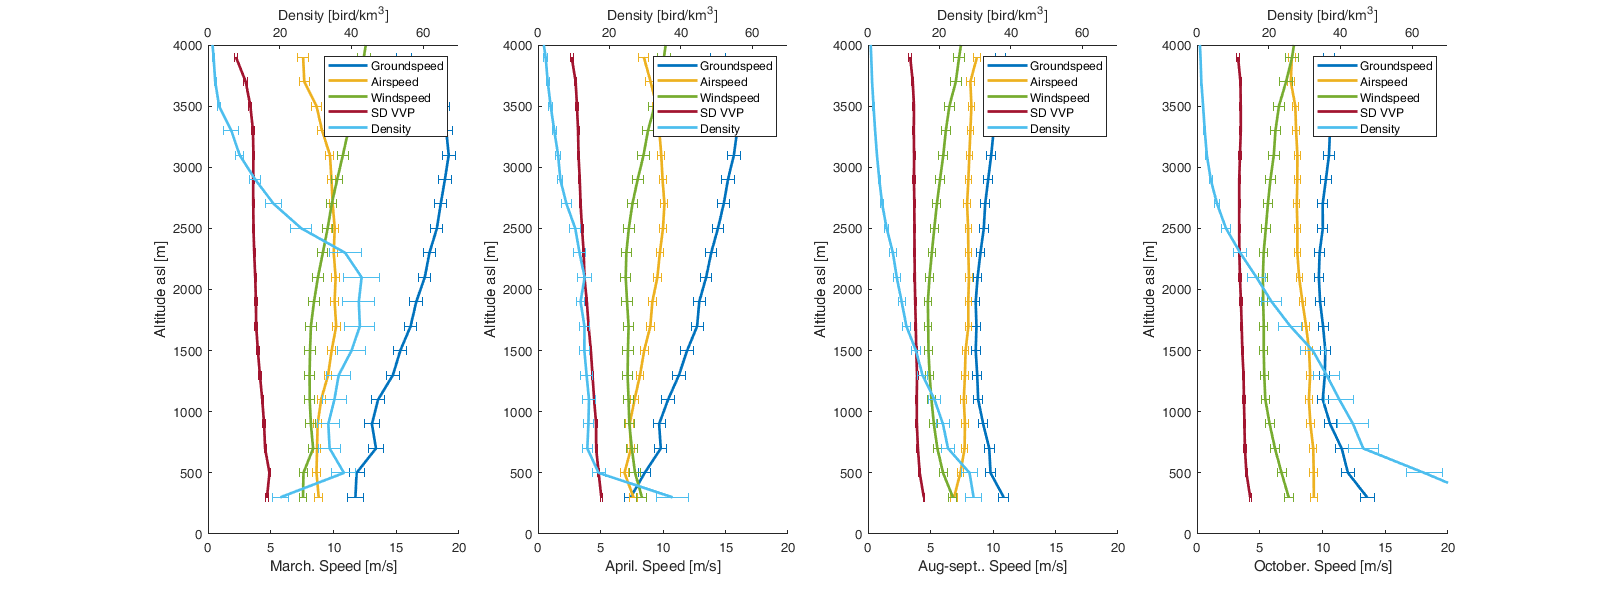

Mg = nan(numel(dc(1).alt),4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    for i_s=1:size(id_s)
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(v_g(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(v_a(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_w(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
    end
end

figure('position',[0 0 1600 600]);
for i_s=1:size(id_s)
    subplot(1,4,i_s); hold on;
    tmp = errorbar(Mg(:,i_s),dc(i_s).alt,Sg(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Ma(:,i_s),dc(i_s).alt,Sa(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Mw(:,i_s),dc(i_s).alt,Sw(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Ms(:,i_s),dc(i_s).alt,Ss(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    xlim([0 20]);ylabel('Altitude asl [m]'); xlabel([id_s_name{i_s} '. Speed [m/s]']); ylim([0 4000]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
    tmp = errorbar(Md(:,i_s),dc(1).alt,Sd(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,i_s),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
    xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 70]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});
end

### Air vs Ground in during the** night**

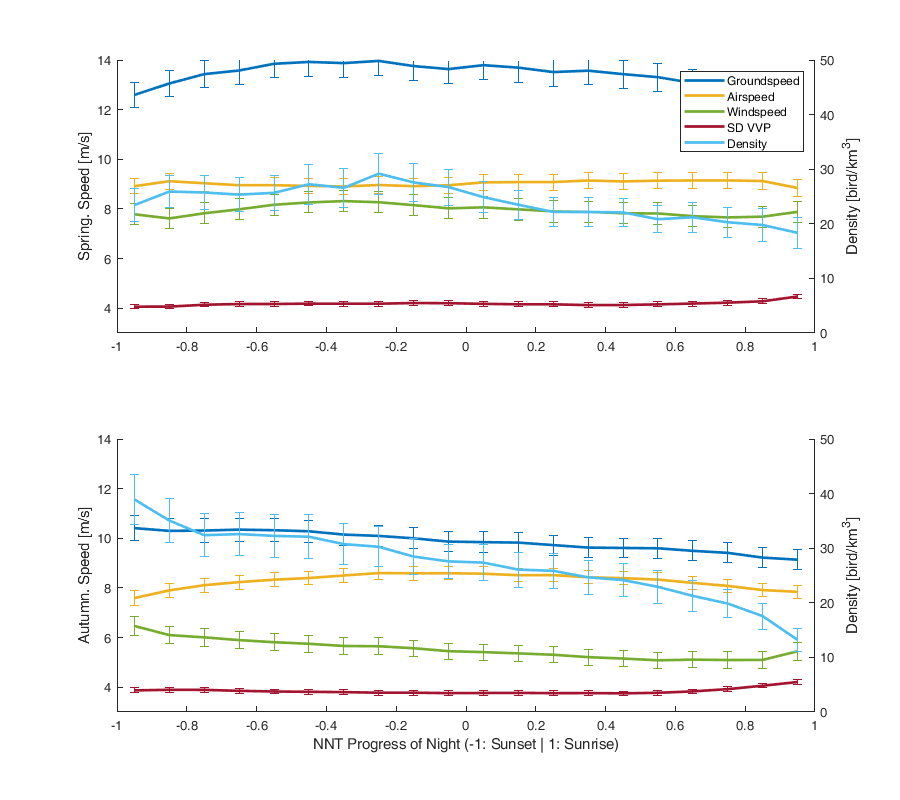

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_sp',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_a),dens(id_a));
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_au',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_a),dens(id_a));
end

figure('position',[0 0 900 800]);
subplot(2,1,1); hold on;
tmp = errorbar(mida, Mg(:,1),Sg(:,1)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,1),Sa(:,1)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,1),Sw(:,1)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,1),Ss(:,1)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,1),'-','Color',tmp.Color,'LineWidth',2); 
ylim([3 14]);ylabel('Altitude asl [m]'); ylabel('Spring. Speed [m/s]'); xlim([-1 1]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,1),Sd(:,1)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,1),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(2,1,2); hold on;
tmp = errorbar(mida, Mg(:,2),Sg(:,2)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,2),Sa(:,2)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,2),Sw(:,2)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,2),Ss(:,2)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,2),'-','Color',tmp.Color,'LineWidth',2);
ylim([3 14]); ylabel('Autumn. Speed [m/s]'); xlim([-1 1]); xlabel('NNT Progress of Night (-1: Sunset | 1: Sunrise)');
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,2),Sd(:,2)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,2),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]); ylim([0 50]); 

We use the NNT which normalize the time between sunset and sunrise between -1 and 1. Both Windspeed and Groundspeed slightly increase in the first hours of the night in Spring maintining the airspeed at a relative constant speed. In autumn, there seems to be an increase of airspeed in thos same hours because groundspeed remains constant while windspeed reduces slightly. The sd_vvp seems to remains relatively constant throughout the night although increase early morning probably due to the start of diunarl movement contamination. 

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    for i_s=1:size(id_s)
        id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_s(i_s,:)',1,numel(dc)),[1 3 2]),1,25,1);
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(v_g(id_a),dens(id_a));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(v_a(id_a),dens(id_a));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_w(id_a),dens(id_a));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_a),dens(id_a));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_a),dens(id_a));
    end
end

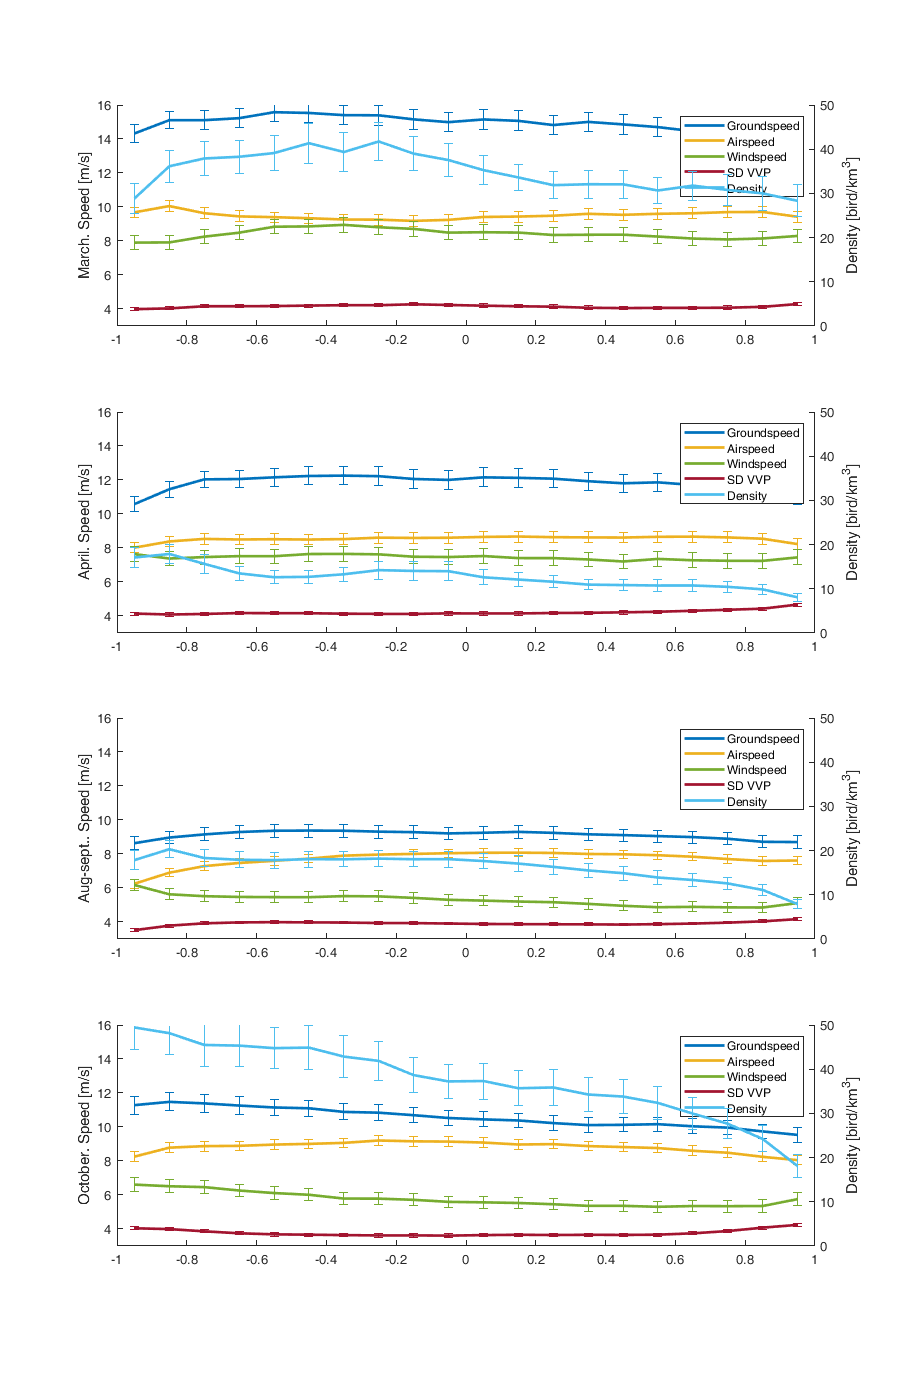

figure('position',[0 0 900 1400]);
for i_s=1:size(id_s)
    subplot(4,1,i_s); hold on;
    tmp = errorbar(mida, Mg(:,i_s),Sg(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Ma(:,i_s),Sa(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Mw(:,i_s),Sw(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Ms(:,i_s),Ss(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    ylim([3 16]);ylabel('Altitude asl [m]'); ylabel([id_s_name{i_s} '. Speed [m/s]']); xlim([-1 1]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
    tmp = errorbar(mida, Md(:,i_s),Sd(:,i_s)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,i_s),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
    ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});
end

**Local Functions**

function [e,h,M,S,A] = histvdens(X,W,binedge,norm)
    if ~exist('binedge','var'), binedge = 0:0.1:30; end
    if ~exist('norm','var'), norm = false; end
    id = ~isnan(X(:))&~isnan(W(:));
    X=X(id); W = W(id);
    if sum(id(:))==0
        e=nan;
        h=nan;
        M=nan;
        S=nan;   
        A=nan;
    else
        % [~,e,Y] = histcounts(X,edges);
        [Y,edge] = discretize(X,binedge,'IncludedEdge','right'); 
        [G,ID] = findgroups(Y);
        h=zeros(numel(edge),1);
        h(ID+1) = splitapply(@sum, W, G);  
        h = h(2:end); % h(1) is for all X outside the bins
        e = 0.5 * (edge(1:end-1) + edge(2:end));
        if norm, h=h./nansum(h); end
        M = X'*W/sum(W);
        S = sqrt(var(X,W));
        A = mean(W.*exp(1i*deg2rad(X)));
    end
end